# ANN

close all;clear;clc;
rng('default')
addpath models\
addpath utils\
load("data/data_rat010_0615_spike_train_selected.mat")
% load("data\simu.mat")
% mPFCspike=input';
% M1spike=output';

## hyper params

0/500...L=-118658.504...mu=1...Lval=-39546.4308...DBRval10.2213
Elapsed time is 68.594190 seconds.


1/500...L=-54425.1269...mu=0.01...Lval=-16831.1347...DBRval3.217
Elapsed time is 69.426439 seconds.


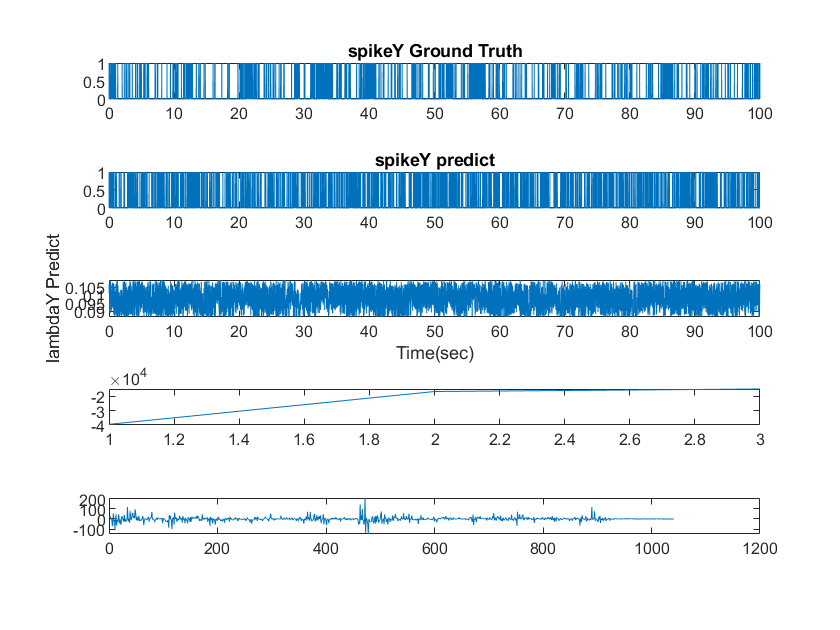

2/500...L=-50452.2728...mu=0.0001...Lval=-15095.7777...DBRval1.2907


preTrainN = 50; % initial multiple times to select better result
H = 10; % temporal history, todo: grid search
Nz = 20; % hidden neuron number, todo: grid search
xi1 = 0.05; % first stage weight parameters initial range param 
xi2 = 0.1; % second stage weight parameters initial range param
mu = 1; % modified LM algorithm param
thres = 1e-3; % stop error tolerance
iterThres = 7; % stop after error over threshold $ times
maxIter = 500; % max iteration num, over needs re-initial
alpha = 0; % Regulization parameter
M1Idx = 1; % select M1 neuron
splitFunc = @(history)splitData(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function
verbose = 0;
W = runANN(H, Nz, xi1, xi2, mu, thres, iterThres, maxIter, alpha, splitFunc, verbose);

% W = runANNgpu(H, Nz, xi1, xi2, mu, thres, iterThres, maxIter, alpha, splitFunc, verbose);